# Exercise 14

clc;
close all;
clear variables;

set(groot, 'defaulttextinterpreter', 'latex');  
set(groot, 'defaultAxesTickLabelInterpreter', 'latex');  
set(groot, 'defaultLegendInterpreter', 'latex');

## Task 1

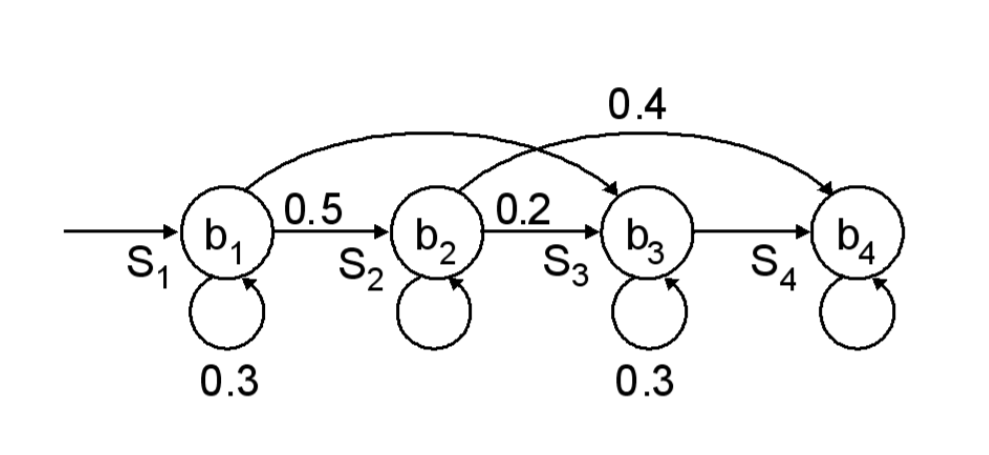

B = [0.3; 0.6; 0.5; 0.8];
B = [B, 1 - B]

B =     0.3000    0.7000
    0.6000    0.4000
    0.5000    0.5000
    0.8000    0.2000


### a)

A = zeros(4, 4);
A(1, 1) = 0.3;
A(1, 2) = 0.5;
A(1, 3) = 1 - sum(A(1, :));

A(2, 3) = 0.2;
A(2, 4) = 0.4;
A(2, 2) = 1 - sum(A(2, :));

A(3, 3) = 0.3;
A(3, 4) = 1 - sum(A(3, :));

A(4, 4) = 1;

A

A =     0.3000    0.5000    0.2000         0
         0    0.4000    0.2000    0.4000
         0         0    0.3000    0.7000
         0         0         0    1.0000


Pi = zeros(4, 1);
Pi(1) = 1

Pi =      1
     0
     0
     0


### b)

111 
112 
113 
122 
123 
124 
133 
134

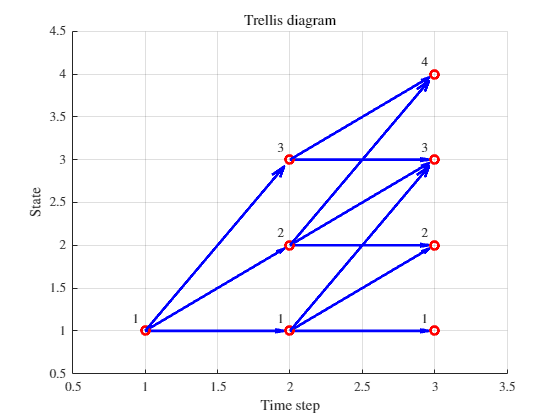

init_node = 1;
max_steps = 3;
trellis(A, init_node, max_steps, 1);

### c)

Q = [1; 3; 4];
P_Q = [];
for i = 1:length(Q)
    if i == 1
        P_Q = Pi(Q(i));
    else
        P_Q = P_Q * A(Q(i - 1), Q(i));
    end
end
P_Q

P_Q = 0.1400

O = [1; 2; 1];
P_O_under_Q = [];
for i = 1:length(O)
    if i == 1
        P_O_under_Q = B(Q(i), O(i));
    else
        P_O_under_Q = P_O_under_Q * B(Q(i), O(i));
    end
end
P_O_under_Q

P_O_under_Q = 0.1200

P_O_and_Q = P_O_under_Q * P_Q

P_O_and_Q = 0.0168

## Task 2

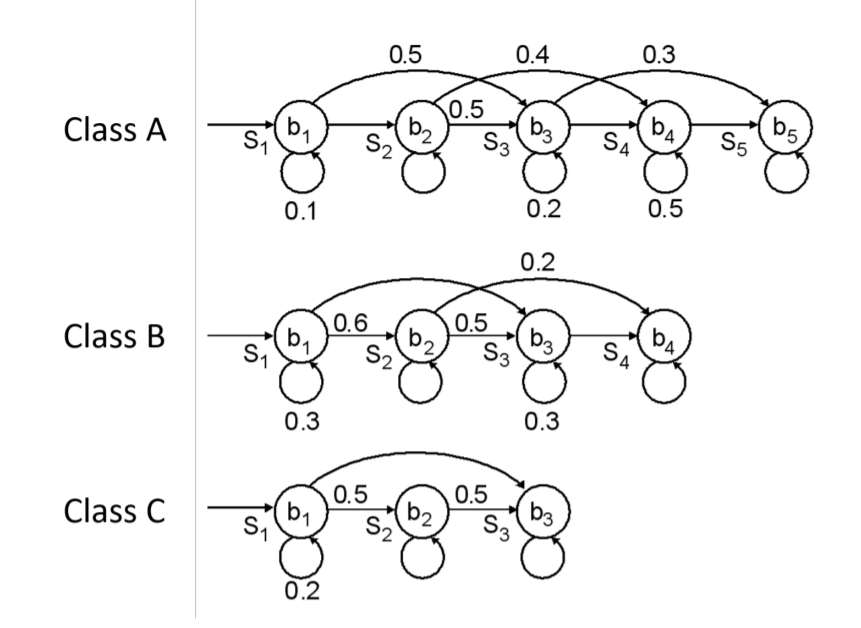

### a)

Class A

A_A = zeros(5, 5);

A_A(1, 1) = 0.1;
A_A(1, 3) = 0.5;
A_A(1, 2) = 1 - sum(A_A(1, :));

A_A(2, 3) = 0.5;
A_A(2, 4) = 0.4;
A_A(2, 2) = 1 - sum(A_A(2, :));

A_A(3, 3) = 0.2;
A_A(3, 5) = 0.3;
A_A(3, 4) = 1 - sum(A_A(3, :));

A_A(4, 4) = 0.5;
A_A(4, 5) = 1 - sum(A_A(4, :));

A_A(5, 5) = 1

A_A =     0.1000    0.4000    0.5000         0         0
         0    0.1000    0.5000    0.4000         0
         0         0    0.2000    0.5000    0.3000
         0         0         0    0.5000    0.5000
         0         0         0         0    1.0000


Pi_A = zeros(5, 1);
Pi_A(1) = 1

Pi_A =      1
     0
     0
     0
     0


Class B

A_B = zeros(4, 4);

A_B(1, 1) = 0.3;
A_B(1, 2) = 0.6;
A_B(1, 3) = 1 - sum(A_B(1, :));

A_B(2, 3) = 0.5;
A_B(2, 4) = 0.2;
A_B(2, 2) = 1 - sum(A_B(2, :));

A_B(3, 3) = 0.3;
A_B(3, 4) = 1 - sum(A_B(3, :));

A_B(4, 4) = 1

A_B =     0.3000    0.6000    0.1000         0
         0    0.3000    0.5000    0.2000
         0         0    0.3000    0.7000
         0         0         0    1.0000


Pi_B = zeros(4, 1);
Pi_B(1) = 1

Pi_B =      1
     0
     0
     0


Class C

A_C = zeros(3, 3);

A_C(1, 1) = 0.2;
A_C(1, 2) = 0.5;
A_C(1, 3) = 1 - sum(A_C(1, :));

A_C(2, 3) = 0.5;
A_C(2, 2) = 1 - sum(A_C(2, :));

A_C(3, 3) = 1

A_C =     0.2000    0.5000    0.3000
         0    0.5000    0.5000
         0         0    1.0000


Pi_C = zeros(3, 1);
Pi_C(1) = 1

Pi_C =      1
     0
     0


### b)

init_node = 1;
max_steps = 3;

paths_A = trellis(A_A, init_node, max_steps, 0);
paths_B = trellis(A_B, init_node, max_steps, 0);
paths_C = trellis(A_C, init_node, max_steps, 0);
num_states = 3;

ending_paths_A = find_ending_paths(paths_A, size(A_A, 1), num_states)

ending_paths_A = 1×1 cell array
    {3×1 double}


ending_paths_B = find_ending_paths(paths_B, size(A_B, 1), num_states)

ending_paths_B = 1×2 cell array
    {3×1 double}    {3×1 double}


ending_paths_C = find_ending_paths(paths_C, size(A_C, 1), num_states)

ending_paths_C = 1×3 cell array
    {3×1 double}    {3×1 double}    {3×1 double}


### c)

@*find_ending_paths* - Of the paths given, find the ones that end with the end node of the model and are of desired number of states

function ending_paths = find_ending_paths(paths, end_state, num_states)

    ending_paths = {};

    for i = 1:length(paths)
        % if the path meets the criteria append it
        if paths{i}(end) == end_state && length(paths{i}) == num_states
            ending_paths{end + 1} = paths{i};
        end
        
        % if the path finds the end state but it's not long enough fill it
        % with self loops in the end state
        if paths{i}(end) == end_state && length(paths{i}) < num_states
            while length(paths{i}) < num_states
                paths{i}(end + 1) = end_state;
            end
    
            ending_paths{end + 1} = paths{i};
        end
    end
end


@*trellis* - traverse the model graph in search of all the possible paths of maximum size starting from the initial node and display the results and the Trellis diagram

function solution_paths = trellis(A, init_node, max_steps, display_results)
    node = init_node;
    node_stack = [];
    visit_stack = [];
    node_stack_shrank_flg = 0;
    
    ban_same_node_flg = 0;
    node_changed_flg = 1;

    solution_paths = {};
    
    if display_results
        figure
        hold on
        % axis equal
        grid on
        title('Trellis diagram')
        xlabel('Time step')
        ylabel('State')
        ylim([0.5, size(A, 1) + 0.5])
        xlim([0.5, max_steps + 0.5])
        
        marked_table = zeros(max_steps, size(A, 1));    % for displaying text only once
    end
    
    % finding all the sequences of length <= max_steps
    while 1
    
        % if node_stack didn't shrink before push it to the stack
        if node_stack_shrank_flg ~= 1
    
            % push node and it's visitees
            node_stack = [node_stack; node]; 
            
            to_visit = zeros(1, size(A, 2));
            for i = 1:size(A, 2)
                if A(node, i) > 0 %&& i ~= node
                    to_visit(i) = 1;
                end
            end
            
            visit_stack = [visit_stack; to_visit];   % push
        end
    
        % if node is end
        if nnz(A(node, :)) == 1 || length(node_stack) == max_steps
            
            if display_results
                prev = [];
                
                % display the results
                for i = 1:length(node_stack)
                    
                    % print the sequence
                    fprintf("%d", node_stack(i))
                    
                    % plot the points and arrows
                    if ~isempty(prev)
        
                        % draw arrows
                        p1 = [prev, node_stack(prev)];
                        p2 = [i, node_stack(i)];
                        dp = p2 - p1;
                        quiver(p1(1),p1(2),dp(1),dp(2),0.96, 'Color', 'b', 'LineWidth', 2)
                        % line([prev, i], node_stack([prev, i]), 'Color', 'b')
                        
                        % text displacement
                        dx = -0.1;
                        dy = 0.14;
                        
                        % display the text on the figure if it hasn't been
                        % displayed before at that location
                        if marked_table(prev, node_stack(prev)) == 0
                            marked_table(prev, node_stack(prev)) = 1;
                            text(p1(1) + dx, p1(2) + dy, num2str(node_stack(prev)))
                        end
        
                        if marked_table(i, node_stack(i)) == 0
                            marked_table(i, node_stack(i)) = 1;
                            text(p2(1) + dx, p2(2) + dy, num2str(node_stack(i)))
                        end
                    end
                    plot(i, node_stack(i), 'ro', 'LineWidth', 2)
        
                    prev = i;
                end
                disp(" ")
            end

            % append solution
            solution_paths{end + 1} = node_stack;
            
            % pop stacks
            visit_stack(end, :) = [];
            node_stack(end) = [];
    
            prev_node = node;
            node = node_stack(end);
            
            % check if node has changed (important for self loops)
            if prev_node == node
                node_changed_flg = 0;
            else
                node_changed_flg = 1;
            end
            
            % if we've reached max timesteps length ban the program from
            % entering the same node through a self loop
            if length(node_stack) == max_steps
                ban_same_node_flg = 1;
            end
        end
        
        % if self loops we're banned and the node has changed lift the ban on
        % self loops
        if ban_same_node_flg == 1 && node_changed_flg
            ban_same_node_flg = 0;
        end
        
        % if there are visitable nodes visit them
        if nnz(visit_stack(end, :)) > 0
    
            node_stack_shrank_flg = 0;
    
            for i = 1:size(A, 1)
    
                % if self loops are banned skip the same node
                if ban_same_node_flg == 1 && node == i
                    continue;
                end
    
                if visit_stack(end, i) == 1
                    visit_stack(end, i) = 0;
                    node = i;
                    break;
                end
            end
        else
    
            % pop stacks
            visit_stack(end, :) = [];
            node_stack(end) = [];
                
            % if the node stack is empty we've done it all, exit the while 1
            % loop
            if isempty(node_stack)
                break;
            end
    
            prev_node = node;
    
            node = node_stack(end);
            
            % check if node has changed (important for self loops)
            if prev_node == node
                node_changed_flg = 0;
            else
                node_changed_flg = 1;
            end
    
            % indicate that the stack shrank so it doesn't get pushed to
            node_stack_shrank_flg = 1;
        end
    end
end